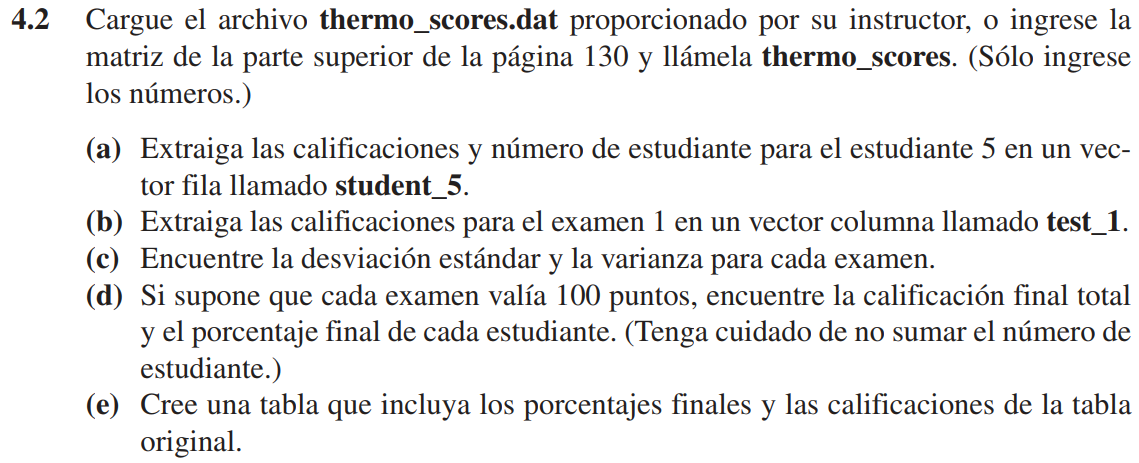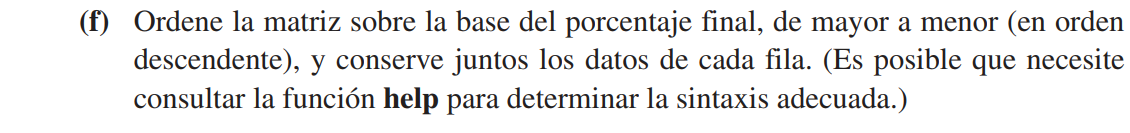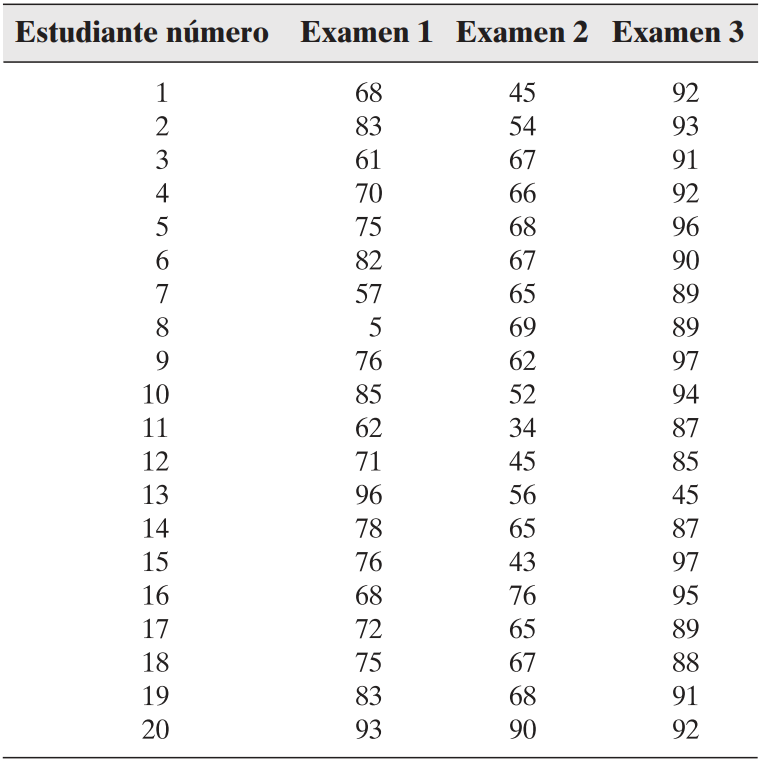

clear

n_student = 1:20;
scores = [
    68 45 92
    83 54 93
    61 67 91
    70 66 92
    75 68 96
    82 67 90
    57 65 89
    05 69 89
    79 62 97
    85 52 94
    62 34 87
    71 45 85
    96 56 45
    78 65 87
    76 43 97
    68 76 95
    72 65 89
    75 67 88
    83 68 91
    93 90 92
    ];
themo_scores = [n_student' scores];

% Literal (a).
student_5 = themo_scores(5,:)

student_5 =      5    75    68    96


% Literal (b).
test_1 = themo_scores(:,2)

test_1 =     68
    83
    61
    70
    75
    82
    57
     5
    79
    85


% Literal (c).
test_var = var(themo_scores(:,2:end))

test_var =   348.3658  164.6947  118.4711


test_std = std(themo_scores(:,2:end))

test_std =    18.6646   12.8333   10.8844


% Literal (d).
final_score = sum(themo_scores(:,2:end)')'

final_score =    205
   230
   219
   228
   239
   239
   211
   163
   238
   231


final_score_over100 = final_score/3

final_score_over100 =    68.3333
   76.6667
   73.0000
   76.0000
   79.6667
   79.6667
   70.3333
   54.3333
   79.3333
   77.0000


% Literal (e).
var_labels = {'Estudiante' 'Examen 1' 'Examen 2' 'Examen 3' 'Nota final'};
results = array2table([themo_scores final_score_over100],"VariableNames",var_labels)

results = 20×5 table
    Estudiante    Examen 1    Examen 2    Examen 3    Nota final
    __________    ________    ________    ________    __________

       1.00        68.00       45.00       92.00        68.33   
       2.00        83.00       54.00       93.00        76.67   
       3.00        61.00       67.00       91.00        73.00   
       4.00        70.00       66.00       92.00        76.00   
       5.00        75.00       68.00       96.00        79.67   
       6.00        82.00       67.00       90.00        79.67   
       7.00        57.00       65.00       89.00        70.33   
       8.00         5.00       69.00       89.00        54.33   
       9.00        79.00       62.00       97.00        79.33   
      10.00        85.00       52.00       94.00        77.00   
      11.00        62.00    

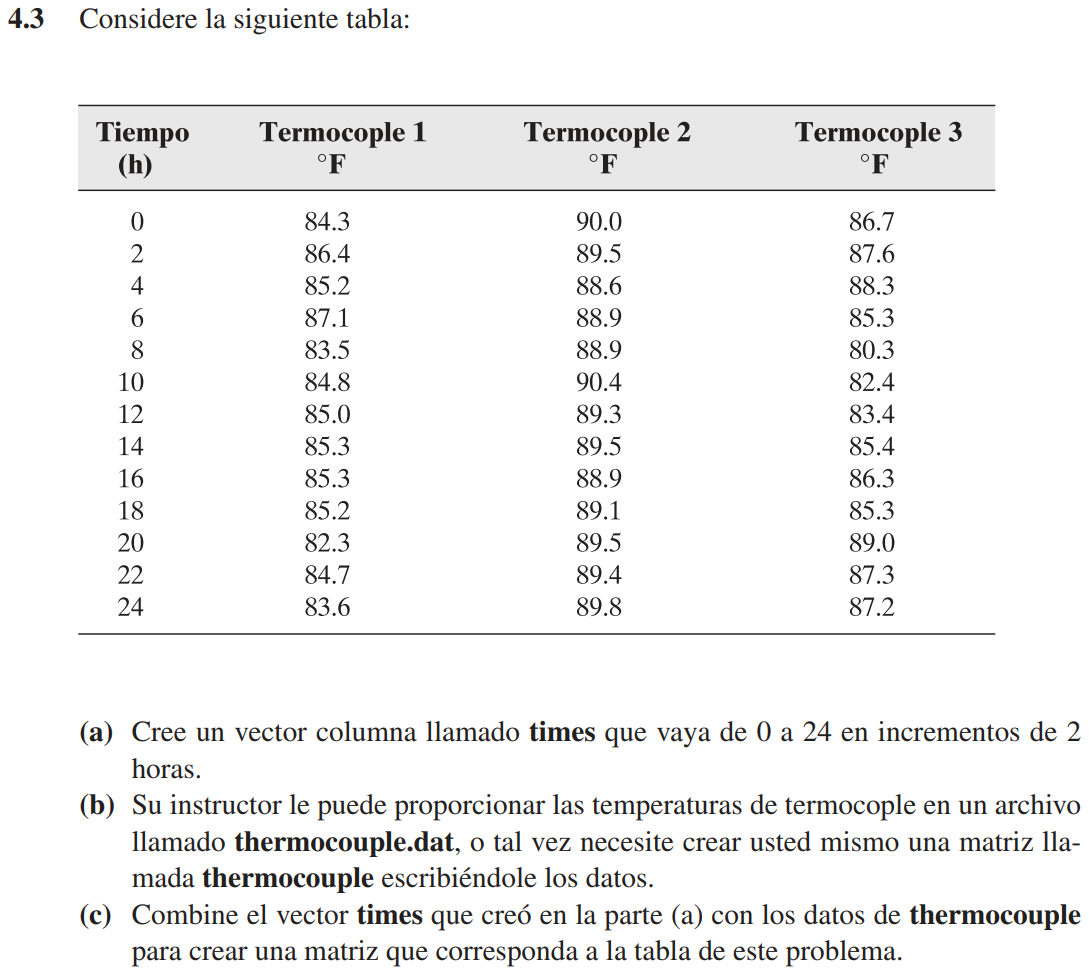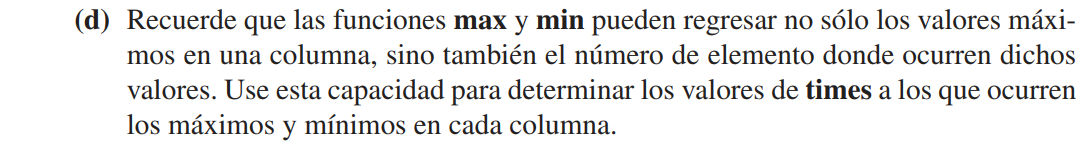

clear

% Literal (a)
times = 0:2:24

times =      0     2     4     6     8    10    12    14    16    18    20    22    24


% Literal (b).
data = [
    84.3 90.0 86.7
    86.4 89.5 87.6
    85.2 88.6 88.3
    87.1 88.9 85.3
    83.5 88.9 80.3
    83.8 90.4 82.4
    85.0 89.3 83.4
    85.3 89.5 85.4
    85.3 88.9 86.3
    85.2 89.1 85.3
    82.3 89.5 89.0
    84.7 89.4 87.3
    83.6 89.8 87.2
    ]

data =    84.3000   90.0000   86.7000
   86.4000   89.5000   87.6000
   85.2000   88.6000   88.3000
   87.1000   88.9000   85.3000
   83.5000   88.9000   80.3000
   83.8000   90.4000   82.4000
   85.0000   89.3000   83.4000
   85.3000   89.5000   85.4000
   85.3000   88.9000   86.3000
   85.2000   89.1000   85.3000


% Literal (c).
thermocouple = [times' data]

thermocouple =          0   84.3000   90.0000   86.7000
    2.0000   86.4000   89.5000   87.6000
    4.0000   85.2000   88.6000   88.3000
    6.0000   87.1000   88.9000   85.3000
    8.0000   83.5000   88.9000   80.3000
   10.0000   83.8000   90.4000   82.4000
   12.0000   85.0000   89.3000   83.4000
   14.0000   85.3000   89.5000   85.4000
   16.0000   85.3000   88.9000   86.3000
   18.0000   85.2000   89.1000   85.3000


% Literal (d).
times = times';
[Tmax, idx_Tmax] = max(thermocouple(:,2:end));
times_Tmax1 = times(idx_Tmax(1))

times_Tmax1 =           6.00


times_Tmax2 = times(idx_Tmax(2))

times_Tmax2 =          10.00


times_Tmax3 = times(idx_Tmax(3))

times_Tmax3 =          20.00



times = times';
[Tmin, idx_Tmin] = min(thermocouple(:,2:end));
times_Tmin1 = times(idx_Tmin(1))

times_Tmin1 =          20.00


times_Tmin2 = times(idx_Tmin(2))

times_Tmin2 =           4.00


times_Tmin3 = times(idx_Tmin(3))

times_Tmin3 =           8.00



fprintf(['Los Termocouple 1, 2 y 3 presentan su valor máximo a las %d, %d y %d horas,' ...
    'respectivamente.\nEn cambio, su valor mínimo es a las %d, %d y %d, respectivamente.'], ...
    times_Tmax1,times_Tmax2,times_Tmax3,times_Tmin1,times_Tmin2,times_Tmin3)

Los Termocouple 1, 2 y 3 presentan su valor máximo a las 6, 10 y 20 horas,respectivamente.
En cambio, su valor mínimo es a las 20, 4 y 8, respectivamente.